# INSTRON Code for communicating with an instrument.

## Instrument Connection

clc; clear;

% Find a GPIB object.
obj1 = instrfind('Type', 'gpib', 'BoardIndex', 0, 'PrimaryAddress', 4, 'Tag', '');


% Create the GPIB object if it does not exist
% otherwise use the object that was found.
if isempty(obj1)
    obj1 = gpib('NI', 0, 4);
else
    fclose(obj1);
    obj1 = obj1(1);
end


% Connect to instrument object, obj1.
fopen(obj1);


## Set Parameters

s = 0.1;        % Travel Speed (in/min)
L_max = 1;      % Max Load (kilo-pounds)
E_max = 1;      % Extension Max (in)

% Mount Sample
% S1 > 0 > ENTER to clear previous values
% LOAD CAL > ENTER
% S1 > TESTING AREA (Above) > 1 > Enter

% Set travel speed
fprintf(obj1, 'K13,'+string(s));

% Set limits, Action is STOP
fprintf(obj1, 'K24,'+string(L_max));
fprintf(obj1, 'K26,'+string(E_max));
fprintf(obj1, 'K30,2');     % Break Action (1 - Cycle, 2 - Return, 3 - Stop)
fprintf(obj1, 'K31,3');     % Load Max Action
fprintf(obj1, 'K32,3');     % Extension Max Action

% Reset Guage Length
fprintf(obj1, 'K21');

% Dir of increasing load down
fprintf(obj1, 'K5');


## Read Data

% Start X-head in downward dir
fprintf(obj1, 'K6');

% Determine if test in progress by querying status
status = query(obj1, 'R0');
tmp = split(status,',');
testing = str2double(tmp(1));

data = {};
i = 1;
t_sample = 50;
nread = 1000/t_sample;
tic
while testing == 2      % Status 2 = DOWN
    str2send = sprintf('R2R3T%dL%d', [t_sample/50, nread]);
    fprintf(obj1, str2send);
    for j=1:nread
        data{i} = fscanf(obj1, '%c\n');
        i = i+1;
        t(i) = toc;
    end
    status = query(obj1, 'R0');
    tmp = split(status,',');
    testing = str2double(tmp(1));
end


## Disconnect and Clean Up

% The following code has been automatically generated to ensure that any
% object manipulated in TMTOOL has been properly disposed when executed
% as part of a function or script.

% Disconnect all objects.
fclose(obj1);

% Clean up all objects.
delete(obj1);
clear obj1;


## Process Data

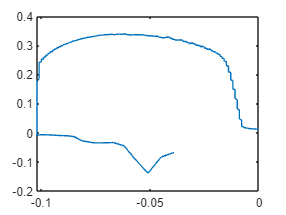

data = data.';
data = cell2mat(cellfun(@str2num,data,'uniform',0));
plot(data(:,2),data(:,1))

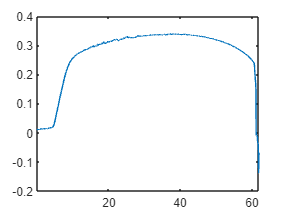

plot(t(1,2:end),data(:,1))